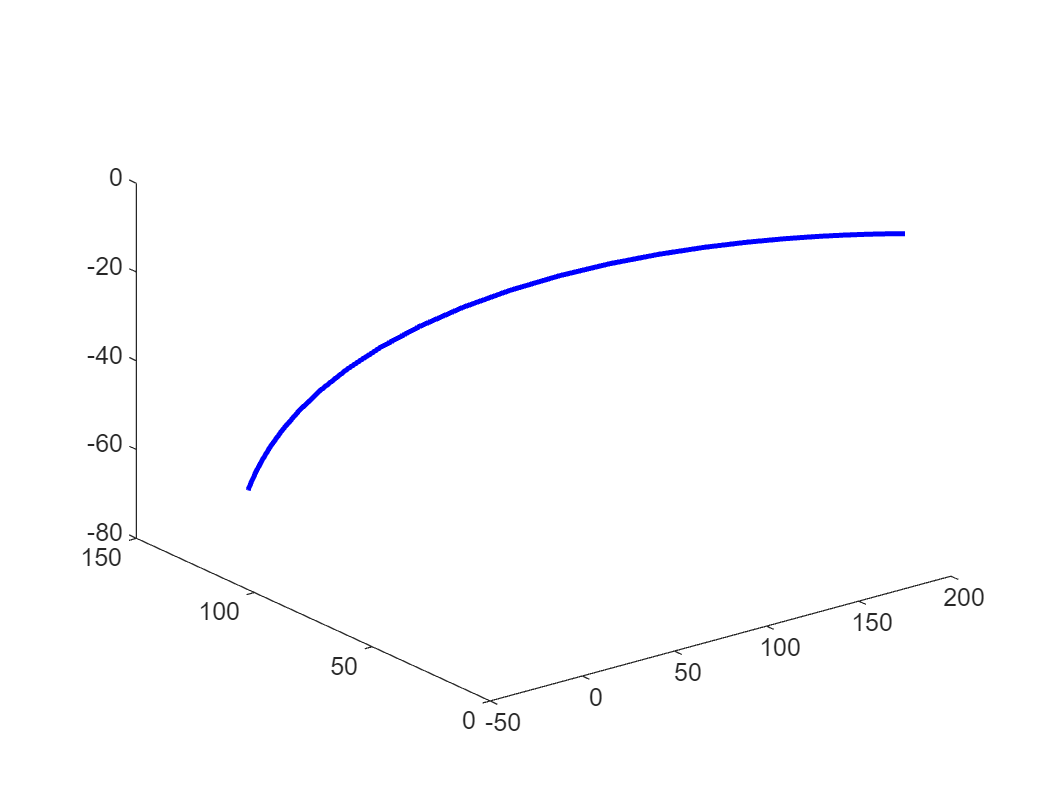

L1 = 75;
L2 = 100;

px = [175 -9.032]';
py = [0  134.715]';
pz = [0  -70.059]';

n = length(px);
theta1 = zeros(n,1);
theta2 = zeros(n,1);
d3 = zeros(n,1);

for i = 1 : n

        %%% Theta_1 %%%
        d = sqrt(px(i)^2 + py(i)^2);
        beta = atan2d(py(i),px(i));
        Ca = (L1^2 + d^2 - L2^2)/(2*L1*d);
        Sap = sqrt(1 - Ca^2);
        
        alpha_p = atan2d(Sap,Ca);
        
        theta1(i,1) = beta - alpha_p;
        
        %%% Theta_2 %%%
        C2 = (d^2 - L1^2 - L2^2)/(2*L1*L2);
        S2p = sqrt(1 - C2^2);
        
        theta2(i,1) = atan2d(S2p,C2);
        
        %%% d3 %%%%%
        d3(i,1) = pz(i);

end

theta1_i = theta1(1,1);
theta1_f = theta1(2,1);

theta2_i = theta2(1,1);
theta2_f = theta2(2,1);

d3_i = d3(1,1);
d3_f = d3(2,1);

tf = 3;
t = 0 : 0.1: tf;
t = t';
nn = length(t);

theta1_t = zeros(nn,1);
theta2_t = zeros(nn,1);
d3_t = zeros(nn,1);

theta1_tt = zeros(nn,1);
theta2_tt = zeros(nn,1);
d3_tt = zeros(nn,1);

theta1_ttt = zeros(nn,1);
theta2_ttt = zeros(nn,1);
d3_ttt = zeros(nn,1);

pxx = zeros(nn,1);
pyy = zeros(nn,1);
pzz = zeros(nn,1);

for ii = 1 : nn
    %%% Articulación_1 %%%%
    a0_1 = theta1_i;
    a1_1 = 0;
    a2_1 = 0;
    a3_1 = 10*(theta1_f - theta1_i)/tf^3;
    a4_1 = -15*(theta1_f - theta1_i)/tf^4;
    a5_1 = 6*(theta1_f - theta1_i)/tf^5;
    
    theta1_t(ii,1) = a0_1 + a1_1*t(ii,1) + a2_1*t(ii,1)^2 + a3_1*t(ii,1)^3 + a4_1*t(ii,1)^4 + a5_1*t(ii,1)^5;
    theta1_tt(ii,1) = a1_1 + 2*a2_1*t(ii,1) + 3*a3_1*t(ii,1)^2 + 4*a4_1*t(ii,1)^3 + 5*a5_1*t(ii,1)^4;
    theta1_ttt(ii,1) = 2*a2_1 + 6*a3_1*t(ii,1) + 12*a4_1*t(ii,1)^2 + 20*a5_1*t(ii,1)^3;

    %%% Articulación_2 %%%%
    a0_2 = theta2_i;
    a1_2 = 0;
    a2_2 = 0;
    a3_2 = 10*(theta2_f - theta2_i)/tf^3;
    a4_2 = -15*(theta2_f - theta2_i)/tf^4;
    a5_2 = 6*(theta2_f - theta2_i)/tf^5;
    
    theta2_t(ii,1) = a0_2 + a1_2*t(ii,1) + a2_2*t(ii,1)^2 + a3_2*t(ii,1)^3 + a4_2*t(ii,1)^4 + a5_2*t(ii,1)^5;
    theta2_tt(ii,1) = a1_2 + 2*a2_2*t(ii,1) + 3*a3_2*t(ii,1)^2 + 4*a4_2*t(ii,1)^3 + 5*a5_2*t(ii,1)^4;
    theta2_ttt(ii,1) = 2*a2_2 + 6*a3_2*t(ii,1) + 12*a4_2*t(ii,1)^2 + 20*a5_2*t(ii,1)^3;

    %%% Articulación_3 %%%%
    a0_3 = d3_i;
    a1_3 = 0;
    a2_3 = 0;
    a3_3 = 10*(d3_f - d3_i)/tf^3;
    a4_3 = -15*(d3_f - d3_i)/tf^4;
    a5_3 = 6*(d3_f - d3_i)/tf^5;
    
    d3_t(ii,1) = a0_3 + a1_3*t(ii,1) + a2_3*t(ii,1)^2 + a3_3*t(ii,1)^3 + a4_3*t(ii,1)^4 + a5_3*t(ii,1)^5;
    d3_tt(ii,1) = a1_3 + 2*a2_3*t(ii,1) + 3*a3_3*t(ii,1)^2 + 4*a4_3*t(ii,1)^3 + 5*a5_3*t(ii,1)^4;
    d3_ttt(ii,1) = 2*a2_3 + 6*a3_3*t(ii,1) + 12*a4_3*t(ii,1)^2 + 20*a5_3*t(ii,1)^3;

    pxx(ii,1) = L1*cosd(theta1_t(ii,1)) + L2*cosd(theta1_t(ii,1) + theta2_t(ii,1));
    pyy(ii,1) = L1*sind(theta1_t(ii,1)) + L2*sind(theta1_t(ii,1) + theta2_t(ii,1));
    pzz(ii,1) = d3_t(ii,1);

end

% subplot(3,3,1)
% plot(t,theta1_t)
% subplot(3,3,4)
% plot(t,theta1_tt)
% subplot(3,3,7)
% plot(t,theta1_ttt)

% subplot(3,3,2)
% plot(t,theta2_t)
% subplot(3,3,5)
% plot(t,theta2_tt)
% subplot(3,3,8)
% plot(t,theta2_ttt)
% 
% subplot(3,3,3)
% plot(t,d3_t)
% subplot(3,3,6)
% plot(t,d3_tt)
% subplot(3,3,9)
% plot(t,d3_ttt)
plot3(pxx,pyy,pzz,'b',LineWidth=2)